# Consistency of our data with Betz

Betz et al 1999 measured tissue fluorescence using a spectrophotometer with a longpass filter to block excitation light.  

    **Autofluorescence imaging and spectroscopy of normal and malignant mucosa in patients with head and neck cancer. **Betz CS, Mehlmann M, Rick K, Stepp H, Grevers G, Baumgartner R, Leunig A *Lasers Surg. Med.*, 1999

The spectrophotometer received light from an endoscope tube that was **placed 12 mm from tissue.**  Light from the tube was also sent to an RGB CCD camera that had a 515 nm longpass filter. Hence, it was possible to measure part of the spectrophotometric signal that reached the central region of the camera. They compared their measurements of a variety of different locations in patients with one healthy volunteer. 

#### Oxygenated hemoglobin

- Betz et al observed dips in autofluorescence at 540 and 575 which they note "correspond to absorption peaks of oxygenated hemoglobin". 

#### Differences between lip and tongue

- Betz et al (1999) observed difference in spectral shape of lip and tongue fluorescence.  Betz also reported that the hard palate had highest fluorescence and that "Only the spectra from the dorsums of tongue evidently differ from the other three averaged spectra" .They did not have a good explanation for the difference in spectral shape.

#### Porphyrin

- Betz observed porphyrin fluorescence at the back of the tongue and on only 10 of the 30 tumors. They concluded that even though others have reported that lesions have an affinity for porphyrins,  the distribution of porphyrins on tumors could not be used to demarcate turmors. Betz did not provide spectral measurements beyond 600 nm, so we cannot compare to our data.

ieInit;
waves = 500:2:590;
symbols = {'kx-','k*-','k^-','ko-'};
T = oeDatabaseCreate;

## Lip, all subjects at 405 nm

Read in the files at all excitation levels and all subjects.  The raw data have non integer wavelengths from the grabit.  That is why we round(wave).

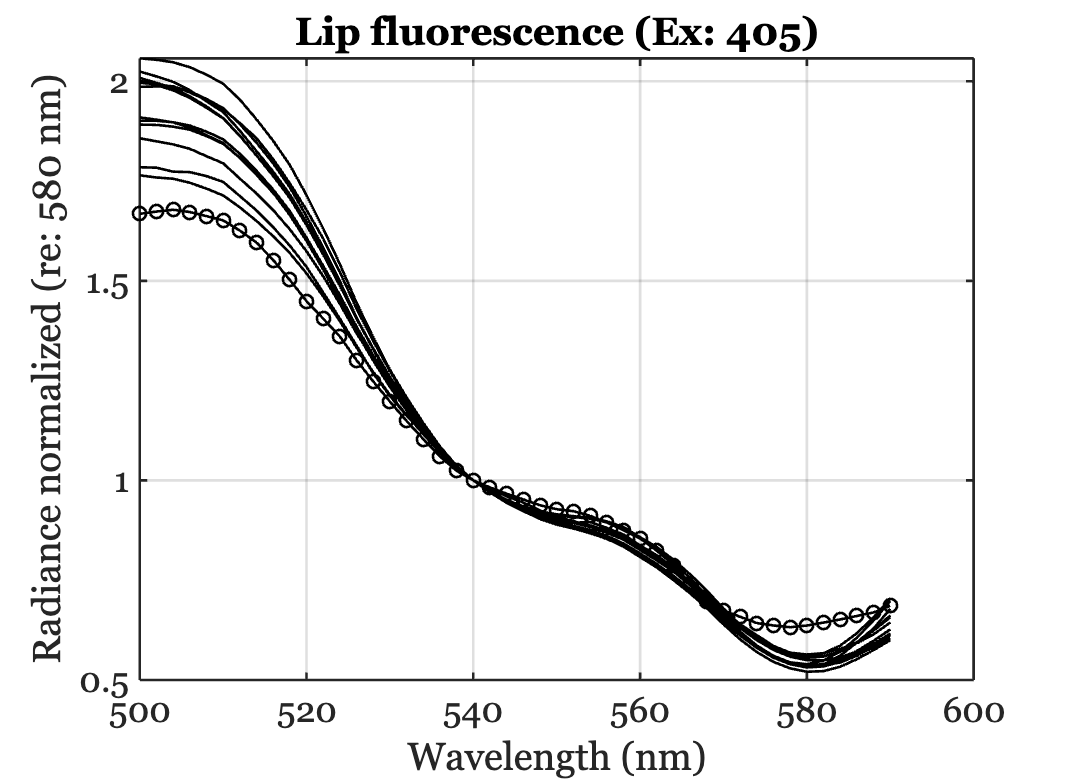

lip    = ieReadSpectra('InnerLipBetz1999.mat',waves);
lip = lip/lip(waves == 540);

eWave = 405;
files405 = ieTableGet(T,...
    'substrate','lip', ...
    'ewave',eWave);

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',540);

ieFigure;
plot(waves,data405,'k-'); hold on;
plot(waves,lip,'ko-');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on; set(gca,'xlim',[500 600]);
title('Lip fluorescence (Ex: 405)');

## Fit Betz cheek from our lip data

veldCheek = data405 * wgts

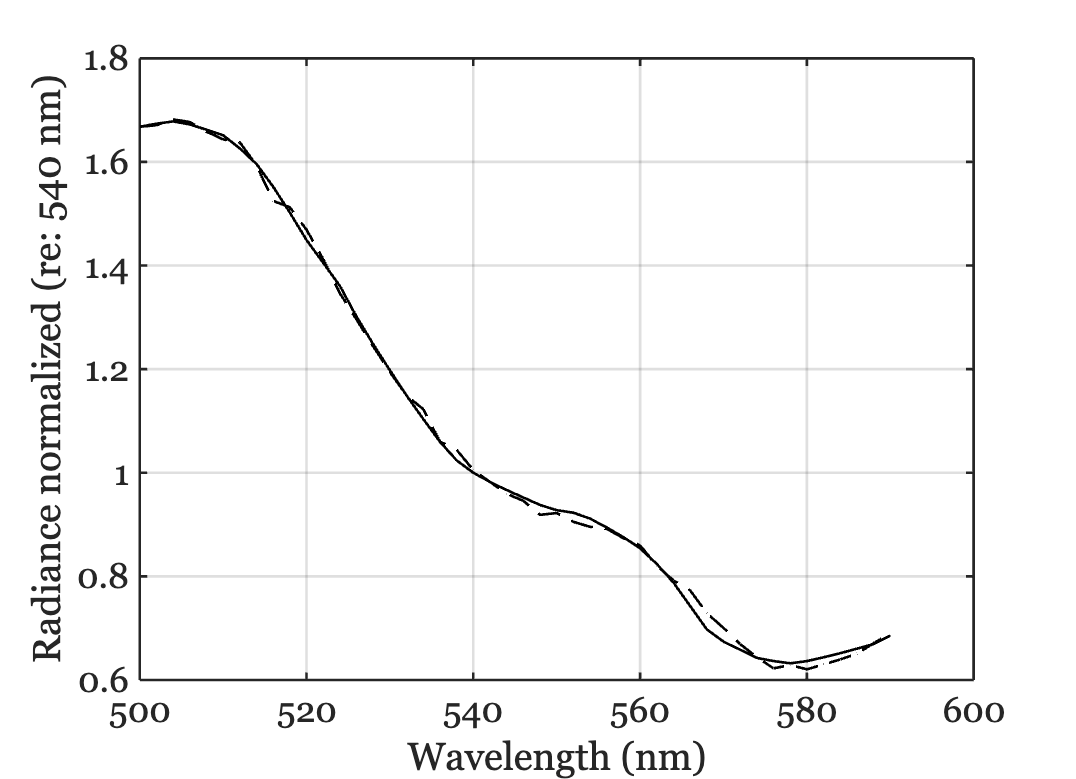

wgts = pinv(data405)*lip;
lipP = data405*wgts;

ieFigure;
plot(waves,lip,'k-',waves,lipP,'k--');
grid on;
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 540 nm)');

fprintf('Percent error: %.3f\n',sqrt(mean(((lip - lipP) ./ lipP).^2)));

Percent error: 0.015


## Tongue, all subjects at 405 nm

Read in the files at all excitation levels

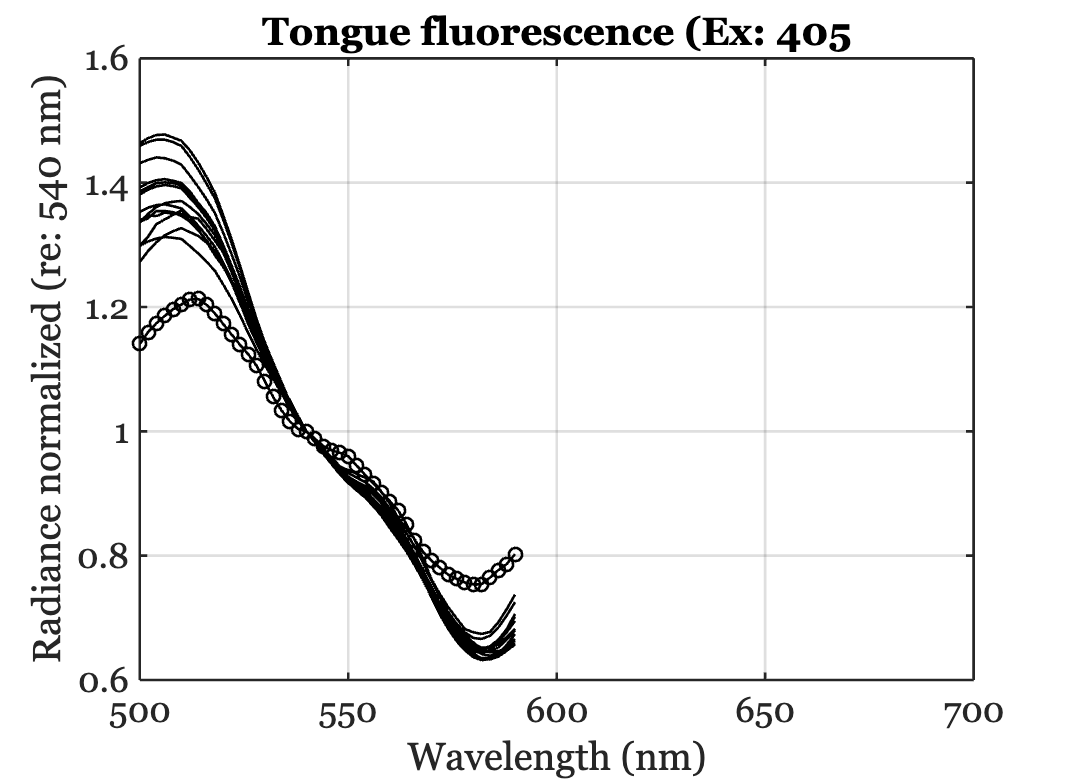

tongue = ieReadSpectra('TongueBetz1999.mat',waves);
tongue = tongue/tongue(waves == 540);


eWave = 405;
files405 = ieTableGet(T,...
    'substrate','tongue', ...
    'ewave',eWave);

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',540);

ieFigure;
plot(waves,data405,'k-'); hold on;
plot(waves,tongue,'ko-');
xlabel('Wavelength (nm)'); ylabel('Radiance normalized (re: 540 nm)');
set(gca,'xlim',[500 700]); grid on;
title('Tongue fluorescence (Ex: 405');

## Fit Betz tongue from our tongues data

veldTongue = data405 * wgts

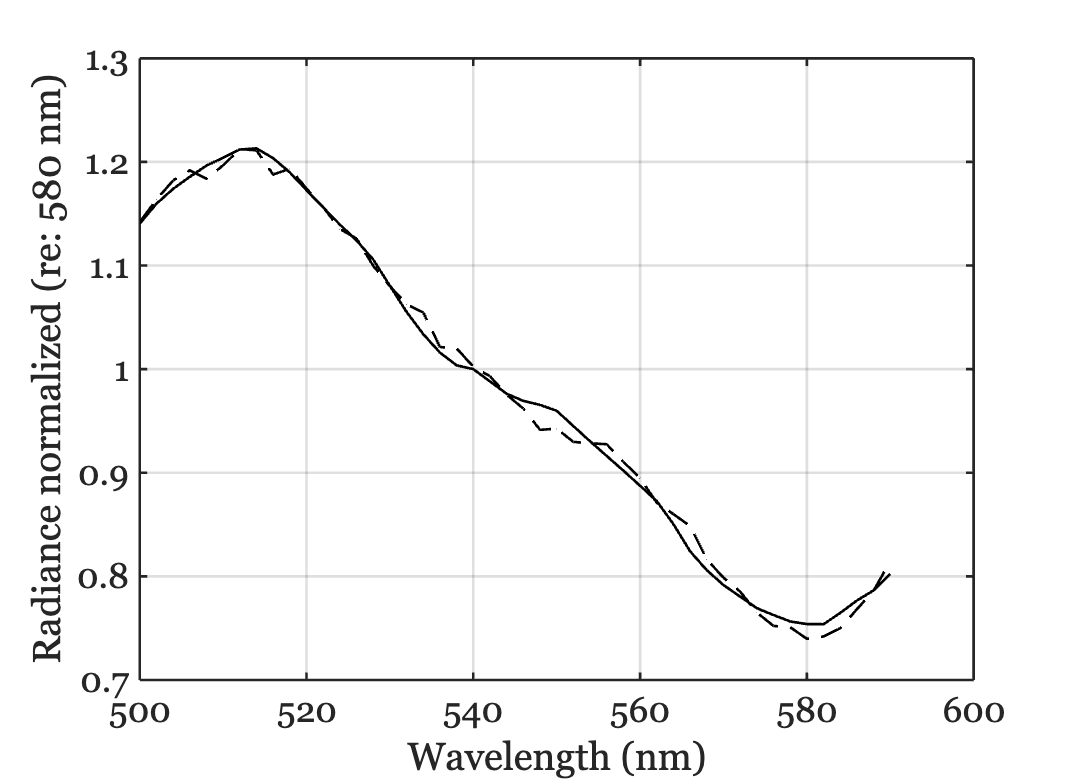

wgts = pinv(data405)*tongue;
tongueP = data405*wgts;

ieFigure;
plot(waves,tongue,'k-',waves,tongueP,'k--');
grid on;
xlabel('Wavelength (nm)'); 
ylabel('Radiance normalized (re: 580 nm)');

fprintf('Percent error: %.3f\n',sqrt(mean(((tongue - tongueP) ./ tongueP).^2)));

Percent error: 0.011
